# Create SAC agent

## Create critic

Create two Q-value critic representations. First, create a critic deep neural network structure.

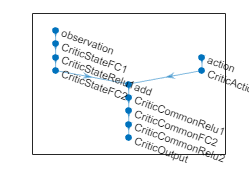

statePath1 = [
    featureInputLayer(numObs,'Normalization','none','Name','observation')
    fullyConnectedLayer(128,'Name','CriticStateFC1')
    reluLayer('Name','CriticStateRelu1')
    fullyConnectedLayer(128,'Name','CriticStateFC2')
    ];
actionPath1 = [
    featureInputLayer(numAct,'Normalization','none','Name','action')
    fullyConnectedLayer(128,'Name','CriticActionFC1')
    ];
commonPath1 = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(32,'Name','CriticCommonFC2')
    reluLayer('Name','CriticCommonRelu2')
    fullyConnectedLayer(1,'Name','CriticOutput')
    ];

criticNet = layerGraph(statePath1);
criticNet = addLayers(criticNet,actionPath1);
criticNet = addLayers(criticNet,commonPath1);
criticNet = connectLayers(criticNet,'CriticStateFC2','add/in1');
criticNet = connectLayers(criticNet,'CriticActionFC1','add/in2');
figure('Name','criticNet','NumberTitle','off')
plot(criticNet)

Create the critic representations. Use the same network structure for both critics. The SAC agent initializes the two networks using different default parameters.

criticOptions = rlRepresentationOptions('Optimizer','adam','LearnRate',criticLearnRate,... 
    'GradientThreshold',1,'L2RegularizationFactor',2e-4);

Unrecognized function or variable 'criticLearnRate'.

critic1 = rlQValueRepresentation(criticNet,obsInfo,actInfo,...
    'Observation',{'observation'},'Action',{'action'},criticOptions);
critic2 = rlQValueRepresentation(criticNet,obsInfo,actInfo,...
    'Observation',{'observation'},'Action',{'action'},criticOptions);

## Create actor

Create an actor deep neural network. Do not add a `tanhLayer` or `scalingLayer` in the mean output path. The SAC agent internally transforms the unbounded Gaussian distribution to the bounded distribution to compute the probability density function and entropy properly.

statePath = [
    featureInputLayer(numObs,'Normalization','none','Name','observation')
    fullyConnectedLayer(256, 'Name','commonFC1')
    reluLayer('Name','CommonRelu')];
meanPath = [
    fullyConnectedLayer(128,'Name','MeanFC1')
    reluLayer('Name','MeanRelu')
    fullyConnectedLayer(numAct,'Name','Mean')
    ];
stdPath = [
    fullyConnectedLayer(128,'Name','StdFC1')
    reluLayer('Name','StdRelu')
    fullyConnectedLayer(numAct,'Name','StdFC2')
    softplusLayer('Name','StandardDeviation')];

concatPath = concatenationLayer(1,2,'Name','GaussianParameters');

actorNetwork = layerGraph(statePath);
actorNetwork = addLayers(actorNetwork,meanPath);
actorNetwork = addLayers(actorNetwork,stdPath);
actorNetwork = addLayers(actorNetwork,concatPath);
actorNetwork = connectLayers(actorNetwork,'CommonRelu','MeanFC1/in');
actorNetwork = connectLayers(actorNetwork,'CommonRelu','StdFC1/in');
actorNetwork = connectLayers(actorNetwork,'Mean','GaussianParameters/in1');
actorNetwork = connectLayers(actorNetwork,'StandardDeviation','GaussianParameters/in2');
figure('Name','actorNetwork','NumberTitle','off')
plot(actorNetwork)

Create a stochastic actor representation using the deep neural network.

actorOptions = rlRepresentationOptions('Optimizer','adam','LearnRate',actorLearnRate,...
    'GradientThreshold',1,'L2RegularizationFactor',1e-5);

actor = rlStochasticActorRepresentation(actorNetwork,obsInfo,actInfo,actorOptions,...
    'Observation',{'observation'});

## Create agent

Specify agent options.

agentOptions = rlSACAgentOptions;
agentOptions.SampleTime = Ts;
agentOptions.DiscountFactor = DiscountFactor;
agentOptions.TargetSmoothFactor = TargetSmoothFactor;
agentOptions.ExperienceBufferLength = ExperienceBufferLength;
agentOptions.MiniBatchSize = MiniBatchSize;

agentOptions.EntropyWeightOptions.EntropyWeight = EntropyWeight;
agentOptions.EntropyWeightOptions.LearnRate = EntropyLearnRate;
agentOptions.EntropyWeightOptions.TargetEntropy = TargetEntropy; %%% pay attention to target entropy
agentOptions.PolicyUpdateFrequency = 1;
agentOptions.ResetExperienceBufferBeforeTraining = 0;
agentOptions.SaveExperienceBufferWithAgent = 1;

Create SAC agent using actor, critics, and options.

agent = rlSACAgent(actor,[critic1 critic2],agentOptions);

To check your agent, use `getAction` to return the action from a random observation.

% getAction(agent,{rand(obsInfo(1).Dimension)})